# trf_mkFigure6

## Descriptions

## Load model parameters

whichData = 'fmri1'; 
dataLoc      = fullfile(fileparts(temporalfMRIRootPath), 'files');

[a, b]    = loadfiles(dataLoc, whichData);
stn       = b.(whichData).stn;
roiNms    = a.(whichData).nm;

prm_tradeOff = b.fmri1.prmTradeOffs;

## Compute parameters (for figure 6A)

params = stn.param(:, 1 : 2);
nRois  = length(roiNms);

for k = 1 : nRois
    idx = (k - 1) * 100 + 1 : k * 100;
    mparam(k, :) = median(params(idx, :));
    sparam(k, :, :) = prctile(params(idx, :), [25, 75]);
end

## Compute summary metrics (for figure 6C)

metric = [stn.derivedParam.r_double; stn.derivedParam.t_isi];

for k = 1 : nRois
    idx = (k - 1) * 100 + 1 : k * 100;
    mmetric(k, :) = median(metric(:, idx), 2);
    smetric(k, :, :) = prctile(metric(:, idx), [25, 75], 2);
end

## Plot Figure 6

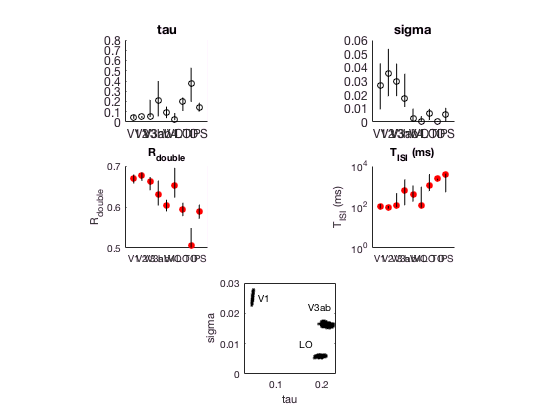

figure (6), clf
paramNm = {'tau', 'sigma'}; metricNm = {'R_{double}', 'T_{ISI} (ms)'};

% plot model parameters
for k = 1 : 2
   subplot(3, 2, k)
   plot(mparam(:, k), 'ko'), hold on,
   for k1 = 1 : nRois
       plot([k1, k1], squeeze(sparam(k1, :, k)), 'k-')
   end 
   box off, set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), axis square, title(paramNm{k}), set(gca, 'fontsize', 12)
end
subplot(3, 2, 1), set(gca, 'ylim', [0, 0.8], 'ytick', 0 : 0.1 : 0.8)
subplot(3, 2, 2), set(gca, 'ylim', [0, 0.06], 'ytick', 0 : 0.01 : 0.06)

% plot summary metrics
subplot(3, 2, 3), plot(mmetric(:, 1), 'ro', 'markerfacecolor', 'r'), hold on
subplot(3, 2, 4), semilogy(mmetric(:, 2), 'ro', 'markerfacecolor', 'r'), hold on

for k1 = 1 : nRois
   subplot(3, 2, 3), plot([k1, k1], squeeze(smetric(k1, 1, :)), 'k-')
   subplot(3, 2, 4), semilogy([k1, k1], squeeze(smetric(k1, 2, :)), 'k-')
end

for k = 1 : 2
    subplot(3, 2, k + 2)
    set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), axis square, box off, title(metricNm{k})
    ylabel(metricNm{k})
end
% plot parameter tradeoffs
subplot(3, 2, 5 : 6), roiIdx = [1, 4, 7];
for k = 1 : length(roiIdx)
    plot(prm_tradeOff(roiIdx(k), :, 1), prm_tradeOff(roiIdx(k), :, 2), 'k.'), hold on
end
text(0.06, 0.025, 'V1'), text(0.17, 0.022, 'V3ab'), text(0.15, 0.01, 'LO')
axis square,  xlabel('tau'), ylabel('sigma'), xlim([0.03, 0.23]), ylim([0, 0.03])